# Multivariant regression

Clear workspace

clear all; clc; close all;

## Initialize variables

**x1**: 1000 uniformly distributed points between 0 and 10

x1 = 10*rand(1000, 1);
% min(x1)
% max(x1)

**x2**: 1000 uniformly distributed points between 10 and 20

x2 = 10+10*rand(1000, 1);
% min(x2)
% max(x2)

**x3**: 1000 uniformly distributed points between 5 and 10

x3 = 5+5*rand(1000, 1);
% min(x3)
% max(x3)

**eps**: random error --> normal distribution ( /mu=0, /sigma=1) = Standard normal distrib

eps = randn(1000, 1);
% std(eps)

**y**: variable to be reconstructed

y = 3 + 2*x1 + x2 - x3 + eps;

## Lineal adjust regression

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    3.2708
    1.9876
    0.9766
   -0.9770



disp(bint)

    2.8162    3.7254
    1.9666    2.0086
    0.9555    0.9976
   -1.0193   -0.9347



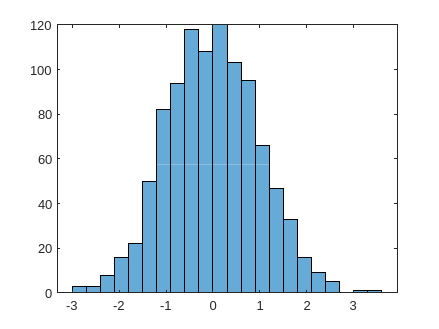


figure(1)
histogram(r)

## Modify variability of error

### sigma = 0 --> no error

y = 3 + 2*x1 + x2 - x3;

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    3.0000
    2.0000
    1.0000
   -1.0000



disp(bint)

    3.0000    3.0000
    2.0000    2.0000
    1.0000    1.0000
   -1.0000   -1.0000



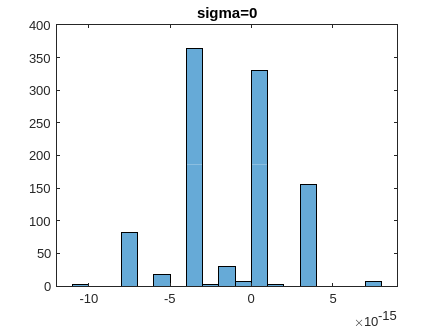


figure(2)
histogram(r)
title('sigma=0')

### sigma = 0.1

y = 3 + 2*x1 + x2 - x3 + 0.1*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    2.9815
    2.0003
    1.0013
   -1.0006



disp(bint)

    2.9357    3.0274
    1.9982    2.0025
    0.9992    1.0034
   -1.0049   -0.9963



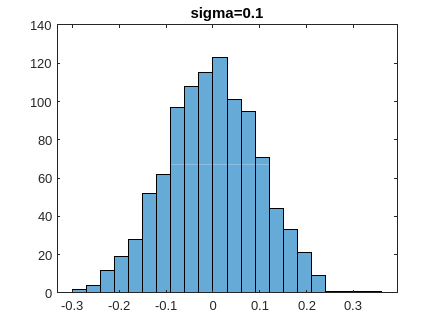


figure(3)
histogram(r)
title('sigma=0.1')

### sigma = 0.5

y = 3 + 2*x1 + x2 - x3 + 0.5*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    3.0023
    1.9963
    1.0001
   -0.9985



disp(bint)

    2.7666    3.2380
    1.9854    2.0072
    0.9892    1.0110
   -1.0205   -0.9766



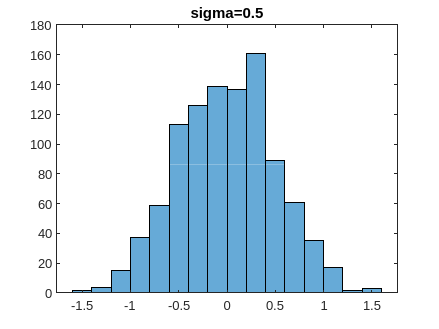


figure(4)
histogram(r)
title('sigma=0.5')

### sigma = 1

y = 3 + 2*x1 + x2 - x3 + 1*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    3.2321
    2.0048
    0.9941
   -1.0190



disp(bint)

    2.7603    3.7040
    1.9830    2.0265
    0.9723    1.0159
   -1.0628   -0.9751



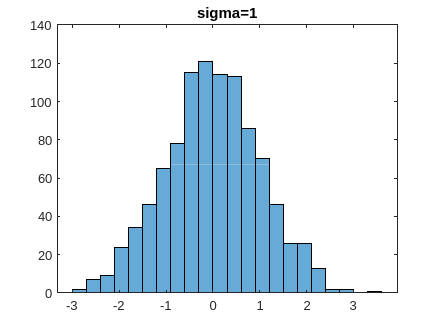


figure(5)
histogram(r)
title('sigma=1')

### sigma = 2

y = 3 + 2*x1 + x2 - x3 + 2*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    3.2054
    1.9946
    0.9827
   -0.9900



disp(bint)

    2.2718    4.1390
    1.9515    2.0377
    0.9395    1.0259
   -1.0768   -0.9031



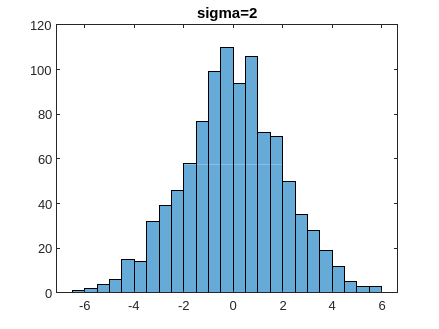


figure(6)
histogram(r)
title('sigma=2')

### sigma = 5

y = 3 + 2*x1 + x2 - x3 + 5*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    2.6195
    2.0082
    0.9258
   -0.8448



disp(bint)

    0.2642    4.9748
    1.8995    2.1170
    0.8168    1.0348
   -1.0639   -0.6257



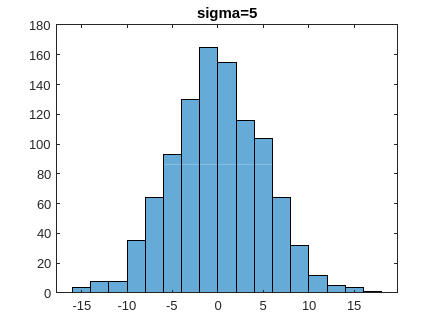


figure(7)
histogram(r)
title('sigma=5')

### sigma = 10

y = 3 + 2*x1 + x2 - x3 + 10*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    5.0488
    2.1114
    0.8475
   -1.0105



disp(bint)

    0.4045    9.6931
    1.8969    2.3259
    0.6325    1.0624
   -1.4425   -0.5785



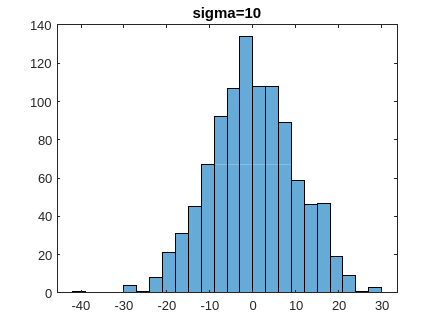


figure(8)
histogram(r)
title('sigma=10')

### sigma = 20

y = 3 + 2*x1 + x2 - x3 + 20*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

   -1.6136
    2.1467
    0.9765
   -0.5695



disp(bint)

  -11.2354    8.0082
    1.7023    2.5911
    0.5312    1.4217
   -1.4646    0.3256



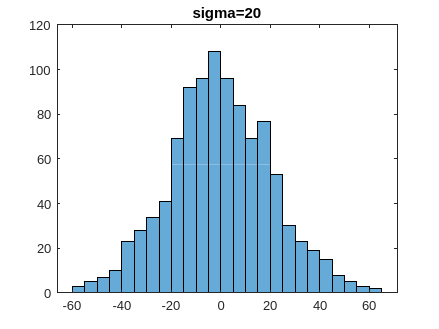


figure(9)
histogram(r)
title('sigma=20')

### sigma = 50

y = 3 + 2*x1 + x2 - x3 + 50*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    4.5941
    1.6255
    0.8296
   -0.5739



disp(bint)

  -18.5470   27.7352
    0.5567    2.6943
   -0.2413    1.9005
   -2.7266    1.5788



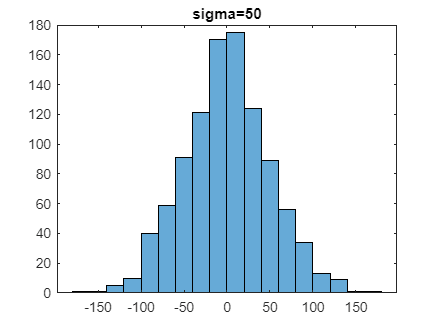


figure(10)
histogram(r)
title('sigma=50')

## Residual analysis for sigma=1

y = 3 + 2*x1 + x2 - x3 + randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    3.2376
    2.0139
    0.9875
   -1.0178



disp(bint)

    2.7740    3.7011
    1.9925    2.0353
    0.9660    1.0089
   -1.0609   -0.9747



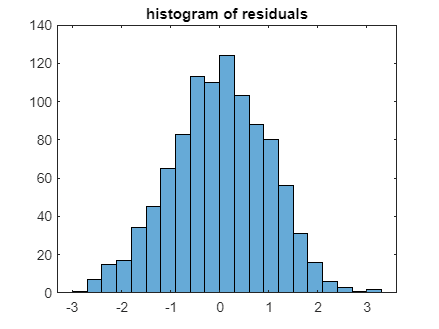

figure(11)
histogram(r)
title('histogram of residuals')

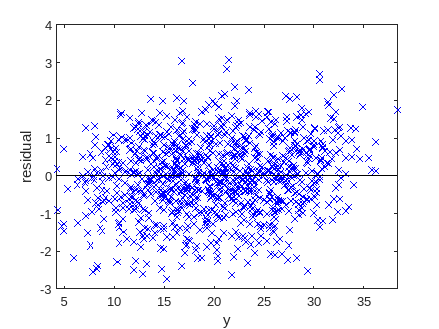

figure(12)
plot(y,r,'xb')
hold on
plot([min(y) max(y)], [0 0], 'k')
xlim([min(y) max(y)])
xlabel('y')
ylabel('residual')
hold off

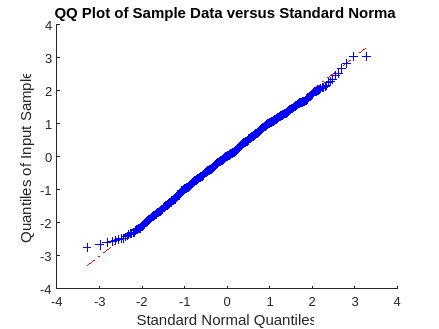

figure(13)
qqplot(r)